#  Rectificador de Onda Completa RL Trifasico no Controlado

Este programa simula el comportamiento de un rectificador trifásico no controlado con una carga resistiva-inductiva (RL). Utilizando un conjunto de diodos que permiten la conducción en un solo sentido, proporcionando así un suministro eléctrico más estable y adecuado para diversas aplicaciones industriales.

En este proceso, los diodos se encargan de permitir el paso de la corriente en una sola dirección, lo que resulta en una forma de onda de salida p ulsante. Esta configuración es especialmente útil en sistemas donde la variabilidad y las fluctuaciones de la corriente de entrada deben ser controladas para garantizar un funcionamiento eficiente.

**Aplicaciones**

Los rectificadores de onda completa trifásicos no controlados son ampliamente utilizados en aplicaciones industriales y comerciales, como en la alimentación de motores eléctricos, fuentes de alimentación de CC para dispositivos electrónicos, y en sistemas de carga de baterías.

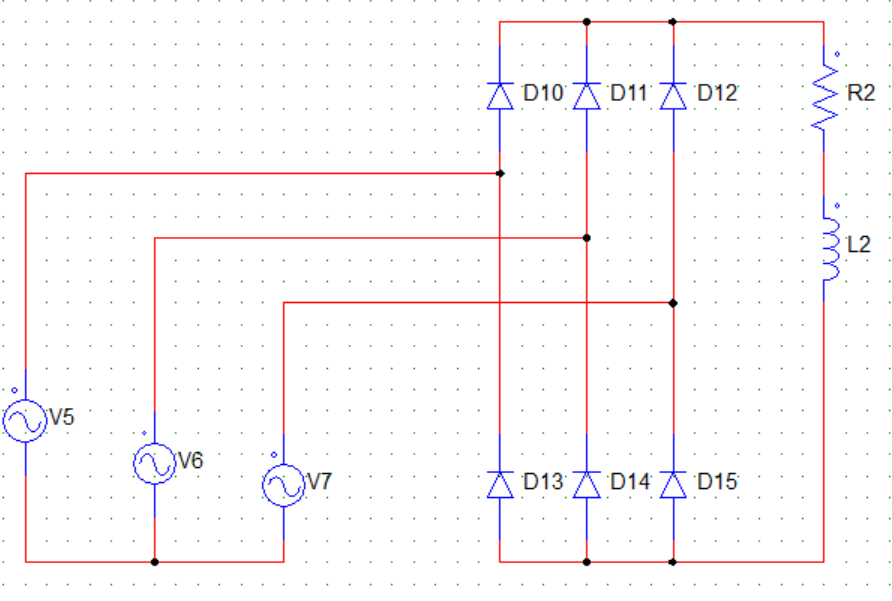

Como se observa rectificador de onda completa trifásico está compuesto por seis diodos dispuestos en un puente. Cada diodo se activa en diferentes momentos durante el ciclo de la señal de entrada, permitiendo que la corriente fluya hacia la carga en ambas mitades de la forma de onda.

Para el caso que se presenta el usuario debe ingresar los siguientes valores.

Vp:170

R: 10

L:0.01

f: 60

Vp = 170;    % Voltaje pico
R = 255;      % Resistencia
L = 0.2;    % Inductancia
f = 60;      % Frecuencia

%% Definición de constantes
w = 2 * pi * f;               % Frecuencia angular
Z = sqrt(R^2 + (w * L)^2);     % Impedancia total
phi = atan(w * L / R);         % Ángulo de desfase debido a la inductancia

%% Definir las variables simbólicas para visualizar las funciones
syms wt x;

% Definir las funciones simbólicas para el voltaje y corriente
Vr_sym = Vp * sin(wt);          % Voltaje de fase R
Vs_sym = Vp * sin(wt - 2*pi/3); % Voltaje de fase S
Vt_sym = Vp * sin(wt + 2*pi/3); % Voltaje de fase T

% Voltajes de línea simbólicos
V_SR_sym = Vs_sym - Vr_sym;
V_RT_sym = Vr_sym - Vt_sym;
V_TS_sym = Vt_sym - Vs_sym;
V_RS_sym = Vr_sym - Vs_sym;
V_TR_sym = Vt_sym - Vr_sym;
V_ST_sym = Vs_sym - Vt_sym;

% Corriente de salida simbólica
I_out_sym = Vp / Z * sin(wt - phi);

% Potencia instantánea simbólica
P_out_sym = I_out_sym * Vp * sin(wt);

%% Mostrar las funciones de Io(wt), Vo(wt), y otras en formato pretty
disp('Función de Io(wt):');

Función de Io(wt):


pretty(I_out_sym)

                    /       5178926258896301 \
2879178618861877 sin| wt - ----------------- |
                    \      18014398509481984 /
----------------------------------------------
               4503599627370496




disp('Función de Vo(wt):');

Función de Vo(wt):


pretty(V_SR_sym)

   /      2 pi \
sin| wt - ---- | 170 - 170 sin(wt)
   \        3  /




disp('Función de Potencia Instantánea P(wt):');

Función de Potencia Instantánea P(wt):


pretty(P_out_sym)

                      /       5178926258896301 \
244730182603259545 sin| wt - ----------------- | sin(wt)
                      \      18014398509481984 /
--------------------------------------------------------
                    2251799813685248



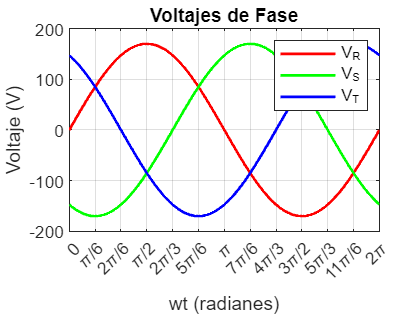


%% Cálculo numérico de los voltajes de entrada trifásicos en el tiempo (radianes)
wt_vals = linspace(0, 2*pi, 1000);    % Valores de tiempo en radianes
Vr_t = double(subs(Vr_sym, wt, wt_vals));  % Evaluar voltaje de fase R
Vs_t = double(subs(Vs_sym, wt, wt_vals));  % Evaluar voltaje de fase S
Vt_t = double(subs(Vt_sym, wt, wt_vals));  % Evaluar voltaje de fase T

% Voltajes de línea numéricos
V_SR = double(subs(V_SR_sym, wt, wt_vals));
V_RT = double(subs(V_RT_sym, wt, wt_vals));
V_TS = double(subs(V_TS_sym, wt, wt_vals));
V_RS = double(subs(V_RS_sym, wt, wt_vals));
V_TR = double(subs(V_TR_sym, wt, wt_vals));
V_ST = double(subs(V_ST_sym, wt, wt_vals));

%% Cálculo de la corriente de salida numérica
I_out = double(subs(I_out_sym, wt, wt_vals));

%% Gráficas de los voltajes de fase
figure;
plot(wt_vals, Vr_t, 'r', 'LineWidth', 1.5); hold on;
plot(wt_vals, Vs_t, 'g', 'LineWidth', 1.5);
plot(wt_vals, Vt_t, 'b', 'LineWidth', 1.5);
grid on;
title('Voltajes de Fase');
xlabel('wt (radianes)');
ylabel('Voltaje (V)');
legend('V_R', 'V_S', 'V_T');
xticks([0 pi/6 pi/3 pi/2 2*pi/3 5*pi/6 pi 7*pi/6 4*pi/3 3*pi/2 5*pi/3 11*pi/6 2*pi]);
xticklabels({'0', '\pi/6', '2\pi/6', '\pi/2', '2\pi/3', '5\pi/6', '\pi', '7\pi/6', '4\pi/3', '3\pi/2', '5\pi/3', '11\pi/6', '2\pi'});

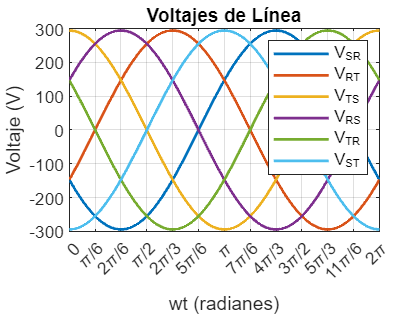


%% Gráficas de los voltajes de línea
figure;
plot(wt_vals, V_SR, 'LineWidth', 1.5); hold on;
plot(wt_vals, V_RT, 'LineWidth', 1.5);
plot(wt_vals, V_TS, 'LineWidth', 1.5);
plot(wt_vals, V_RS, 'LineWidth', 1.5);
plot(wt_vals, V_TR, 'LineWidth', 1.5);
plot(wt_vals, V_ST, 'LineWidth', 1.5);
grid on;
title('Voltajes de Línea');
xlabel('wt (radianes)');
ylabel('Voltaje (V)');
legend('V_{SR}', 'V_{RT}', 'V_{TS}', 'V_{RS}', 'V_{TR}', 'V_{ST}');
xticks([0 pi/6 pi/3 pi/2 2*pi/3 5*pi/6 pi 7*pi/6 4*pi/3 3*pi/2 5*pi/3 11*pi/6 2*pi]);
xticklabels({'0', '\pi/6', '2\pi/6', '\pi/2', '2\pi/3', '5\pi/6', '\pi', '7\pi/6', '4\pi/3', '3\pi/2', '5\pi/3', '11\pi/6', '2\pi'});

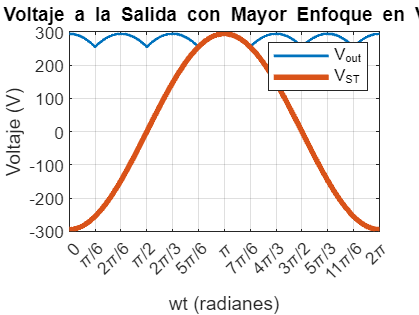


%% Voltaje a la salida con mayor trazo en V_ST
V_out = max([V_SR; V_RT; V_TS; V_RS; V_TR; V_ST]);  % Máximo de los voltajes de línea

figure;
plot(wt_vals, V_out, 'LineWidth', 1.5); hold on;
plot(wt_vals, V_ST, 'LineWidth', 3);  % Mayor trazo para V_ST
grid on;
title('Voltaje a la Salida con Mayor Enfoque en V_{ST}');
xlabel('wt (radianes)');
ylabel('Voltaje (V)');
legend('V_{out}', 'V_{ST}');
xticks([0 pi/6 pi/3 pi/2 2*pi/3 5*pi/6 pi 7*pi/6 4*pi/3 3*pi/2 5*pi/3 11*pi/6 2*pi]);
xticklabels({'0', '\pi/6', '2\pi/6', '\pi/2', '2\pi/3', '5\pi/6', '\pi', '7\pi/6', '4\pi/3', '3\pi/2', '5\pi/3', '11\pi/6', '2\pi'});

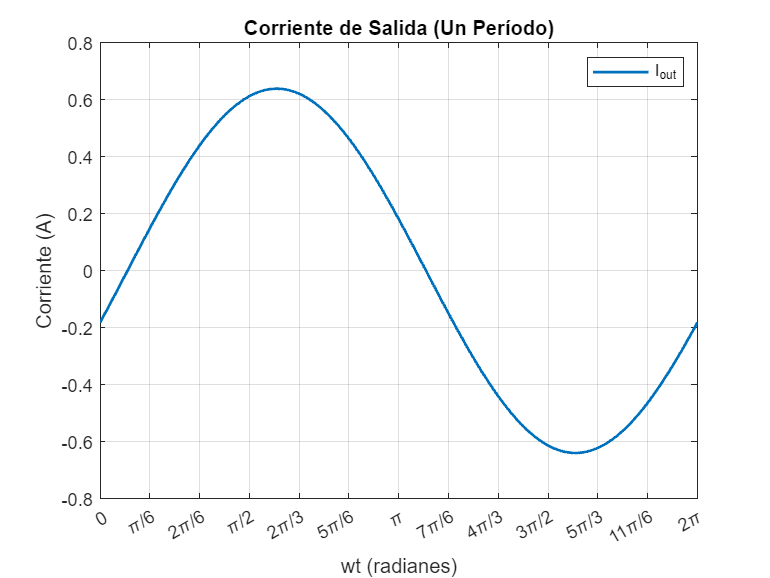


%% Gráfica de la corriente de salida
figure;
plot(wt_vals, I_out, 'LineWidth', 1.5);
grid on;
title('Corriente de Salida (Un Período)');
xlabel('wt (radianes)');
ylabel('Corriente (A)');
legend('I_{out}');
xlim([0 2*pi]);
xticks([0 pi/6 pi/3 pi/2 2*pi/3 5*pi/6 pi 7*pi/6 4*pi/3 3*pi/2 5*pi/3 11*pi/6 2*pi]);
xticklabels({'0', '\pi/6', '2\pi/6', '\pi/2', '2\pi/3', '5\pi/6', '\pi', '7\pi/6', '4\pi/3', '3\pi/2', '5\pi/3', '11\pi/6', '2\pi'});

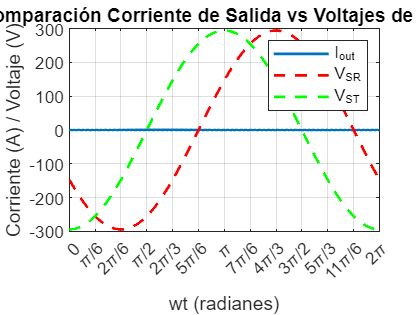


%% Comparación de la corriente de salida vs voltajes de línea
figure;
plot(wt_vals, I_out, 'LineWidth', 1.5); hold on;
plot(wt_vals, V_SR, 'r--', 'LineWidth', 1.5);  % Voltaje V_SR en línea punteada
plot(wt_vals, V_ST, 'g--', 'LineWidth', 1.5);  % Voltaje V_ST en línea punteada
grid on;
title('Comparación Corriente de Salida vs Voltajes de Línea');
xlabel('wt (radianes)');
ylabel('Corriente (A) / Voltaje (V)');
legend('I_{out}', 'V_{SR}', 'V_{ST}');
xticks([0 pi/6 pi/3 pi/2 2*pi/3 5*pi/6 pi 7*pi/6 4*pi/3 3*pi/2 5*pi/3 11*pi/6 2*pi]);
xticklabels({'0', '\pi/6', '2\pi/6', '\pi/2', '2\pi/3', '5\pi/6', '\pi', '7\pi/6', '4\pi/3', '3\pi/2', '5\pi/3', '11\pi/6', '2\pi'});


%% Cálculo de la potencia promedio
P_out = I_out .* V_out;  % Potencia instantánea (producto de corriente y voltaje a la salida)
P_promedio = (1 / (2*pi)) * trapz(wt_vals, P_out);  % Potencia promedio usando integral numérica

disp(['Potencia promedio: ', num2str(P_promedio), ' W']);

Potencia promedio: 2.889e-15 W


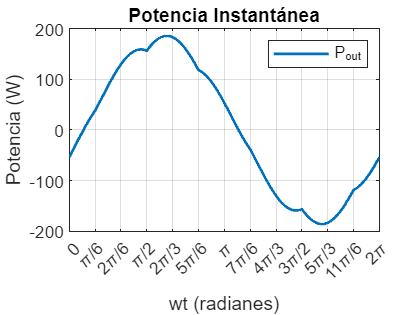


%% Gráfica de la potencia instantánea
figure;
plot(wt_vals, P_out, 'LineWidth', 1.5);
grid on;
title('Potencia Instantánea');
xlabel('wt (radianes)');
ylabel('Potencia (W)');
legend('P_{out}');
xticks([0 pi/6 pi/3 pi/2 2*pi/3 5*pi/6 pi 7*pi/6 4*pi/3 3*pi/2 5*pi/3 11*pi/6 2*pi]);
xticklabels({'0', '\pi/6', '2\pi/6', '\pi/2', '2\pi/3', '5\pi/6', '\pi', '7\pi/6', '4\pi/3', '3\pi/2', '5\pi/3', '11\pi/6', '2\pi'});

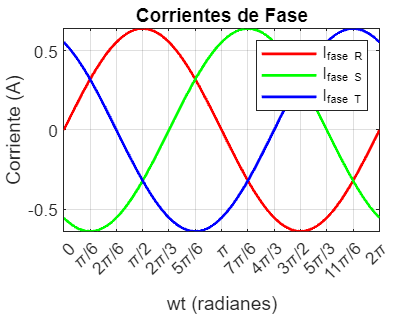


%% Cálculo de la corriente de fase
I_fase_R = Vr_t / Z;  % Corriente de fase para fase R
I_fase_S = Vs_t / Z;  % Corriente de fase para fase S
I_fase_T = Vt_t / Z;  % Corriente de fase para fase T

% Gráfica de las corrientes de fase
figure;
plot(wt_vals, I_fase_R, 'r', 'LineWidth', 1.5); hold on;
plot(wt_vals, I_fase_S, 'g', 'LineWidth', 1.5);
plot(wt_vals, I_fase_T, 'b', 'LineWidth', 1.5);
grid on;
title('Corrientes de Fase');
xlabel('wt (radianes)');
ylabel('Corriente (A)');
legend('I_{fase R}', 'I_{fase S}', 'I_{fase T}');
xticks([0 pi/6 pi/3 pi/2 2*pi/3 5*pi/6 pi 7*pi/6 4*pi/3 3*pi/2 5*pi/3 11*pi/6 2*pi]);
xticklabels({'0', '\pi/6', '2\pi/6', '\pi/2', '2\pi/3', '5\pi/6', '\pi', '7\pi/6', '4\pi/3', '3\pi/2', '5\pi/3', '11\pi/6', '2\pi'});

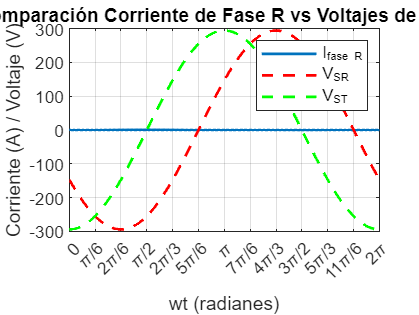


%% Comparación de las corrientes de fase con los voltajes de línea
figure;
plot(wt_vals, I_fase_R, 'LineWidth', 1.5); hold on;
plot(wt_vals, V_SR, 'r--', 'LineWidth', 1.5);  % Voltaje V_SR en línea punteada
plot(wt_vals, V_ST, 'g--', 'LineWidth', 1.5);  % Voltaje V_ST en línea punteada
grid on;
title('Comparación Corriente de Fase R vs Voltajes de Línea');
xlabel('wt (radianes)');
ylabel('Corriente (A) / Voltaje (V)');
legend('I_{fase R}', 'V_{SR}', 'V_{ST}');
xticks([0 pi/6 pi/3 pi/2 2*pi/3 5*pi/6 pi 7*pi/6 4*pi/3 3*pi/2 5*pi/3 11*pi/6 2*pi]);
xticklabels({'0', '\pi/6', '2\pi/6', '\pi/2', '2\pi/3', '5\pi/6', '\pi', '7\pi/6', '4\pi/3', '3\pi/2', '5\pi/3', '11\pi/6', '2\pi'});


%% Cálculo de los coeficientes a1 y b1 para el cálculo del THD
% Expresiones para b1
expr_b1_1 = (sqrt(3) * Vp / Z) * (-cos(x + (2 * pi / 6) - phi) + exp(-(x + (2 * pi / 6) - 5 * pi / 6) / (w * L / R)) * ...
    (sin(phi) / (1 - exp(-pi / (3 * tan(phi)))))) * sin(x);
expr_b1_2 = (sqrt(3) * Vp / Z) * (-cos(x + (4 * pi / 6) - phi) + exp(-(x + (4 * pi / 6) - 5 * pi / 6) / (w * L / R)) * ...
    (sin(phi) / (1 - exp(-pi / (3 * tan(phi)))))) * sin(x);
expr_b1_3 = (sqrt(3) * Vp / Z) * (-cos(x - (2 * pi / 6) - phi) + exp(-(x - (2 * pi / 6) - 5 * pi / 6) / (w * L / R)) * ...
    (sin(phi) / (1 - exp(-pi / (3 * tan(phi)))))) * sin(x);
expr_b1_4 = (sqrt(3) * Vp / Z) * (-cos(x - (4 * pi / 6) - phi) + exp(-(x - (4 * pi / 6) - 5 * pi / 6) / (w * L / R)) * ...
    (sin(phi) / (1 - exp(-pi / (3 * tan(phi)))))) * sin(x);

% Calcular las integrales para b1
b1_1 = (1 / pi) * int(expr_b1_1, x, 3 * pi / 6, 5 * pi / 6);
b1_2 = (1 / pi) * int(expr_b1_2, x, pi / 6, 3 * pi / 6);
b1_3 = (1 / pi) * int(expr_b1_3, x, 7 * pi / 6, 9 * pi / 6);
b1_4 = (1 / pi) * int(expr_b1_4, x, 9 * pi / 6, 11 * pi / 6);

% Sumar y restar los términos para obtener b1
b1 = double(b1_1 + b1_2 - b1_3 - b1_4);
disp(['Coeficiente b1: ', num2str(b1)]);

Coeficiente b1: 1.2163



% Expresiones para a1
expr_a1_1 = (sqrt(3) * Vp / Z) * (-cos(x + (2 * pi / 6) - phi) + exp(-(x + (2 * pi / 6) - 5 * pi / 6) / (w * L / R)) * ...
    (sin(phi) / (1 - exp(-pi / (3 * tan(phi)))))) * cos(x);
expr_a1_2 = (sqrt(3) * Vp / Z) * (-cos(x + (4 * pi / 6) - phi) + exp(-(x + (4 * pi / 6) - 5 * pi / 6) / (w * L / R)) * ...
    (sin(phi) / (1 - exp(-pi / (3 * tan(phi)))))) * cos(x);
expr_a1_3 = (sqrt(3) * Vp / Z) * (-cos(x - (2 * pi / 6) - phi) + exp(-(x - (2 * pi / 6) - 5 * pi / 6) / (w * L / R)) * ...
    (sin(phi) / (1 - exp(-pi / (3 * tan(phi)))))) * cos(x);
expr_a1_4 = (sqrt(3) * Vp / Z) * (-cos(x - (4 * pi / 6) - phi) + exp(-(x - (4 * pi / 6) - 5 * pi / 6) / (w * L / R)) * ...
    (sin(phi) / (1 - exp(-pi / (3 * tan(phi)))))) * cos(x);

% Calcular las integrales para a1
a1_1 = (1 / pi) * int(expr_a1_1, x, 3 * pi / 6, 5 * pi / 6);
a1_2 = (1 / pi) * int(expr_a1_2, x, pi / 6, 3 * pi / 6);
a1_3 = (1 / pi) * int(expr_a1_3, x, 7 * pi / 6, 9 * pi / 6);
a1_4 = (1 / pi) * int(expr_a1_4, x, 9 * pi / 6, 11 * pi / 6);

% Sumar y restar los términos para obtener a1
a1 = double(a1_1 + a1_2 - a1_3 - a1_4);
disp(['Coeficiente a1: ', num2str(a1)]);

Coeficiente a1: -0.0055904



% Cálculo de I1_RMS (primer armónico)
I1_RMS = sqrt((b1^2 + a1^2)) / sqrt(2);
disp(['Primer armónico I1_RMS: ', num2str(I1_RMS), ' A']);

Primer armónico I1_RMS: 0.86009 A



%% Cálculo del THD (Distorsión Armónica Total)
I_R_RMS = 22.95;  % Corriente de fase RMS (ajústala si lo necesitas)
THD = sqrt((I_R_RMS^2 / I1_RMS^2) - 1);


%% Mostrar los valores calculados numéricamente
disp(['Corriente de salida (I_{out}): ', num2str(max(I_out)), ' A']);

Corriente de salida (I_{out}): 0.6393 A


disp(['Voltaje de salida (V_{out}): ', num2str(max(V_out)), ' V']);

Voltaje de salida (V_{out}): 294.4486 V


disp(['Potencia promedio: ', num2str(P_promedio), ' W']);

Potencia promedio: 2.889e-15 W


disp(['Corriente RMS de la fase R: ', num2str(rms(I_fase_R)), ' A']);

Corriente RMS de la fase R: 0.45183 A


disp(['Corriente RMS de la fase S: ', num2str(rms(I_fase_S)), ' A']);

Corriente RMS de la fase S: 0.45217 A


disp(['Corriente RMS de la fase T: ', num2str(rms(I_fase_T)), ' A']);

Corriente RMS de la fase T: 0.45217 A


disp(['THD: ', num2str(THD * 100), ' %']);

THD: 2666.4411 %
